clc; clear; close all;
addpath('functions/');

n = 200;
x1 = 5;
v1 = 1;
t = 1;
sigmaA = 0.2;
sigmaN = 20;
bias=0.2;
A = normrnd(0, sigmaA, 1, n)+bias;
Noise = normrnd(0, sigmaN, 1, n);

G = [(t^2)/2; t];
F = [1, t; 0, 1];
H = [1, 0];

ErrSum=zeros(1,n);
M=100;


BiasCorrection = [bias, 0];
figure; hold on  
for i=1:length(BiasCorrection)
  
    for j=1:M
        [ X, Z ] = calcAccStateSpace( A, Noise, x1, v1, F, G, H );
        [ Xk, SigmaX ] = calcKalman(Z, sigmaA, sigmaN, x1, v1, F, G, H, BiasCorrection(i) );
        ErrCur = ( X(1,:) - Xk(1,:) ).^2;
        ErrSum = ErrSum + ErrCur;
    end
    FinalError = ( ErrSum(3:end)./(M-1) ).^0.5;
    plot(FinalError);


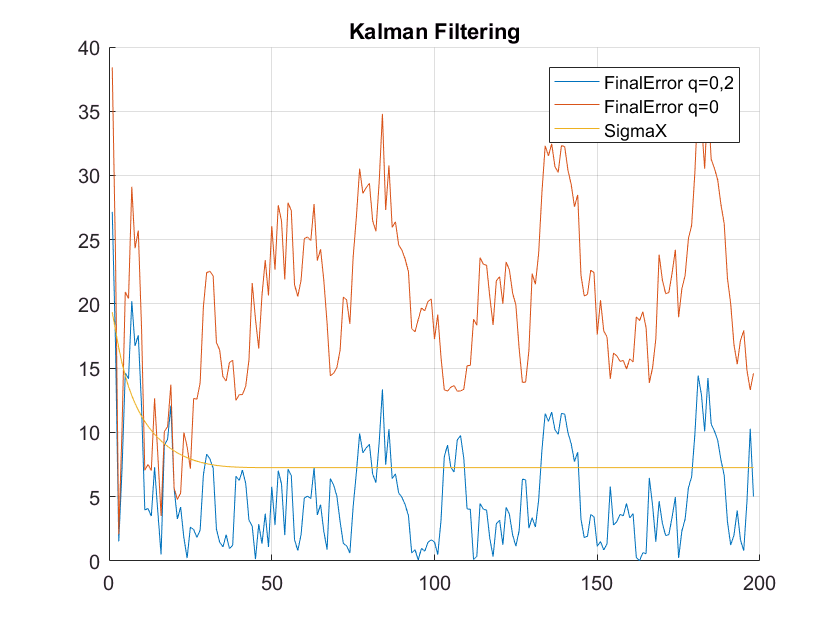

end
plot(SigmaX(3:end));
grid
legend('FinalError q=0,2','FinalError q=0','SigmaX');
title('Kalman Filtering');